% You should change the current folder to the folder-
% where the project file is located so that you don't get the error.
clc
clear
close all


%%%%%%%%%%%%%%%%%%%%%

## in this part, we load the sound file

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[y , fs]    = audioread('C:\Users\pc world\Desktop\S&S_FinalProject_14022\testmusic.wav');
load("C:\Users\pc world\Desktop\S&S_FinalProject_14022\filters.mat")

player      = audioplayer(y , fs);

%play the sound
%play(player)

%%%%%%%%%%%%
%define matrix A
A           = [ 0   0   1   0   0 ; ...
                0   0   0   0   1 ; ...
                0   0   0   1   0 ; ...
               .05  0   0   0   0 ; ...
                0   1   0   0   0];
ts = 1/ fs;
t = 0:ts:(length(y)-1)*ts ;
band1_f= fs/10;
band2_f= 2*(fs/10);
band3_f= 3*(fs/10);
band4_f= 4*(fs/10);
c1 = cos (2*pi*band1_f*t) ;
c2 = cos (2*pi*band2_f*t) ;
c3 = cos (2*pi*band3_f*t) ;
%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% You have to fill in this part    |   |          %
%                                  |   |          %
%                                 \     /         %
%                                  \   /          %
%                                   \ /           %
%                                    .            %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## computing the inverse matrix

you should descramble band acording to inverse matrix

%%%%%%%%%%%%%%%%%%%%%%%%%
Ainv        = zeros(size(A));
Ainv = inv(A);
disp(Ainv)

     0     0     0    20     0
     0     0     0     0     1
     1     0     0     0     0
     0     0     1     0     0
     0     1     0     0     0



## spectrum of sound

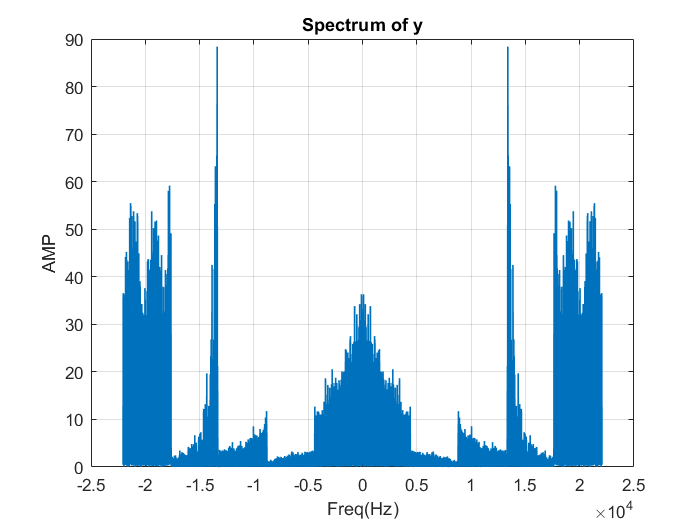

%%%%%%%%%%%%%%%%%%%%%%%%%
% use FFT function defined in example
FFT(y,fs);title('Spectrum of y');

## decomposing the input into 5 bands

%%%%%%%%%%%%%%%%%%%%%%%%%
% Decompose the input into 5 bands using the provided filters
y1 = filter(Band1, y);
y2 = filter(Band2, y);
y3 = filter(Band3, y);
y4 = filter(Band4, y);
y5 = filter(Band5,y);
Y = [y1, y2, y3, y4, y5];

## Band1

x1      = zeros(length(y),1);
x1      = filter(Band1,x1);

## Band2

x2      = zeros(length(y) , 1);
x2      = filter(Band2,x2);

## Band3

x3      = zeros(length(y),1);
x3      = filter(Band3,x3);

## Band4

x4      = zeros(length(y),1);
x4      = filter(Band4,x4);

## Band5

x5      = zeros(length(y),1);
x5      = filter(Band5,x5);

## Decryption

X = [x1, x2, x3, x4, x5];
X = Y * Ainv';
x1 = X(:,1);
x2 = X(:,2);
x3 = X(:,3);
x4 = X(:,4);
x5 = X(:,5);
x1 = x1 .*c3';
x1 = filter(Band1,2*x1);
x2 = x2 .*c3';
x2 = filter(Band2,2*x2);
x3 = x3.*c2';
x3 = filter(Band3,2*x3);
x4 = x4 .*c1';
x4 = filter(Band4,2*x4);
x5 = x5 .*c3';
x5 = filter(Band5,2*x5);



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                                    .            %
%                                   / \           %
%                                  /   \          %
%                                 /     \         %
%                                  |   |          %
%                                  |   |          %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%
% check whether the decompositon is ok
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x       = x1 + x2 + x3 + x4 + x5;

player  = audioplayer(x , fs);
%play(player)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%save vector x as a sound in the curent folder
audiowrite('C:\Users\pc world\Desktop\S&S_FinalProject_14022\output.wav' , x , fs);

## frequency spectrum of xi and yi

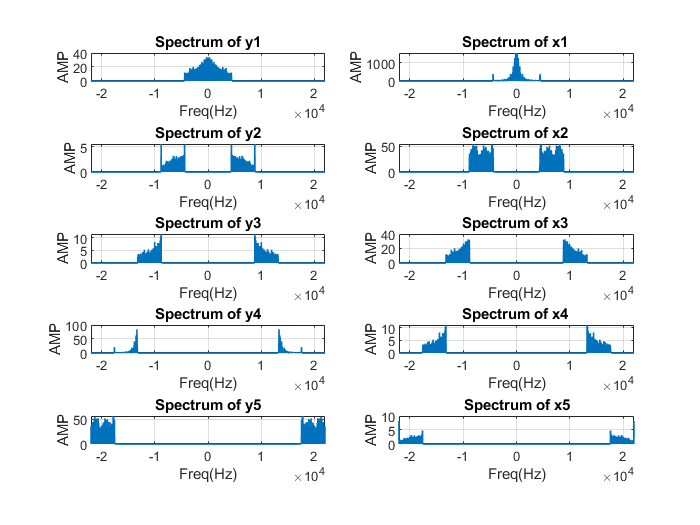

% Plot the frequency spectrum of xi and yi in the same figure
figure;
subplot(5,2,1); FFT(y1, fs); title('Spectrum of y1');
subplot(5,2,2); FFT(x1, fs); title('Spectrum of x1 ');
subplot(5,2,3); FFT(y2, fs); title('Spectrum of y2');
subplot(5,2,4); FFT(x2, fs); title('Spectrum of x2 ');
subplot(5,2,5); FFT(y3, fs); title('Spectrum of y3');
subplot(5,2,6); FFT(x3, fs); title('Spectrum of x3 ');
subplot(5,2,7); FFT(y4, fs); title('Spectrum of y4');
subplot(5,2,8); FFT(x4, fs); title('Spectrum of x4 ');
subplot(5,2,9); FFT(y5, fs); title('Spectrum of y5');
subplot(5,2,10); FFT(x5, fs); title('Spectrum of x5');

## Spectrum of real sound

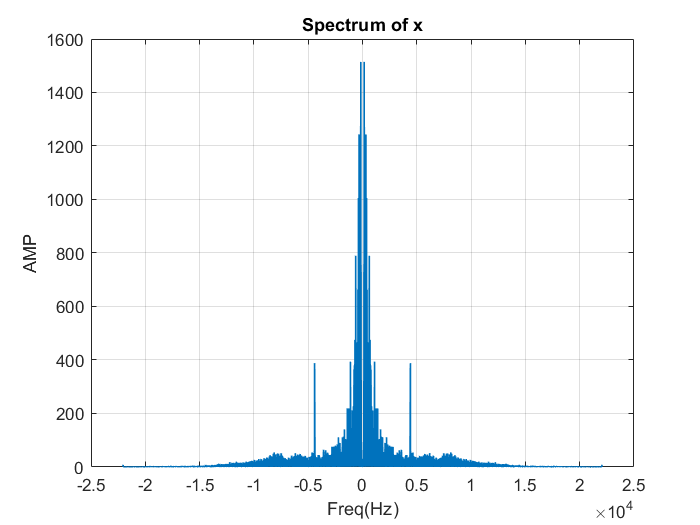

figure;
FFT(x,fs);title('Spectrum of x');

## fft method

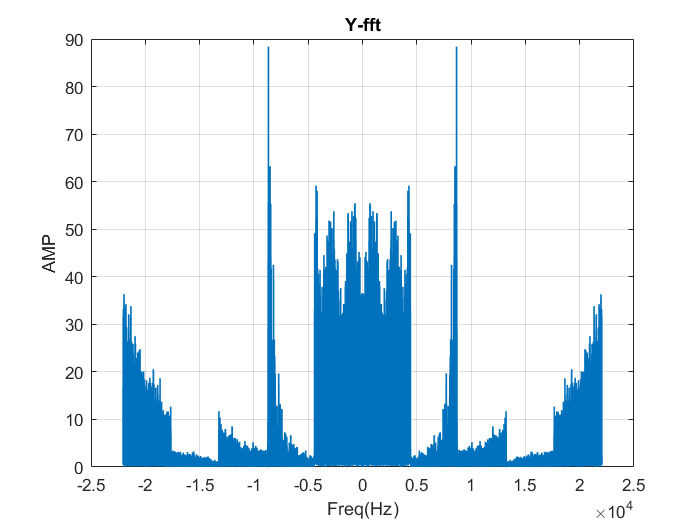

Y_fft=fft(y);
N = numel(y);
freq = (-N/2:N/2-1)/N* fs;
% figure
plot(freq,(abs(Y_fft)),'LineWidth',1);
grid on
ylabel ('AMP')
xlabel('Freq(Hz)')
title('Y-fft');

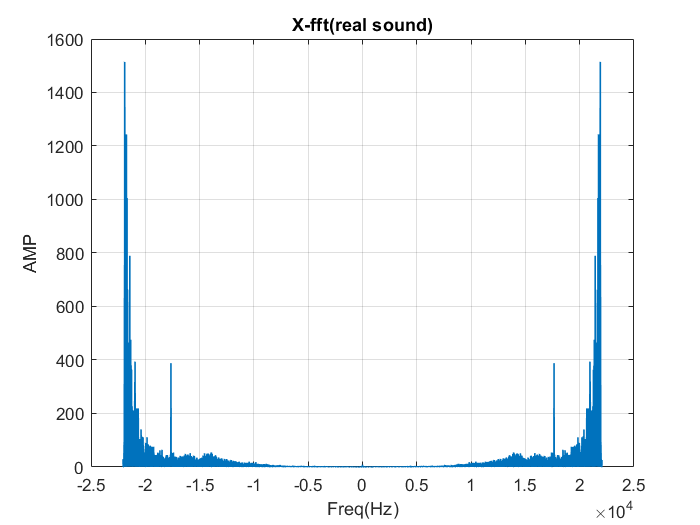

X_fft1=fft(x);
N = numel(x);
freq = (-N/2:N/2-1)/N* fs;
% figure
plot(freq,(abs(X_fft1)),'LineWidth',1);
grid on
ylabel ('AMP')
xlabel('Freq(Hz)')
title('X-fft(real sound)');

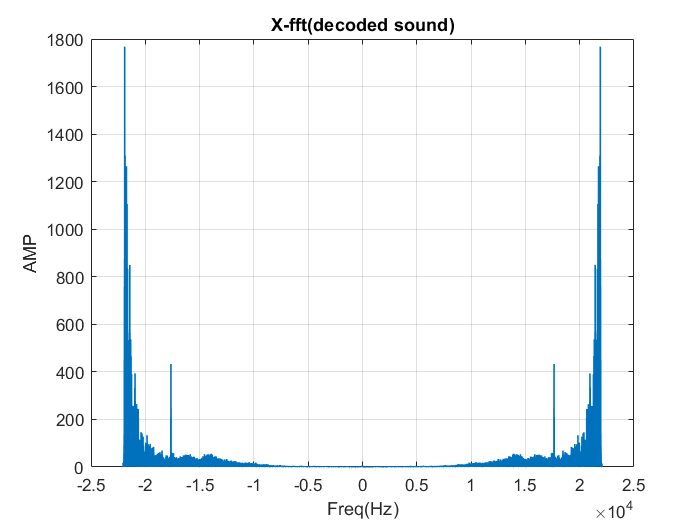

% changing the elements
X_fft(1:123480,1)=20*(Y_fft(370441:493920,1));
X_fft(123481:246960,1)=(Y_fft(493921:617400,1));
X_fft(246961:370440,1)=(Y_fft(1:123480,1));
X_fft(370441:493920,1)=(Y_fft(246961:370440,1));
X_fft(493921:617400,1)=(Y_fft(123481:246960,1));

X_fft(617401:740880,1)=(Y_fft(987841:1111320,1));
X_fft(740881:864360,1)=(Y_fft(864361:987840,1));
X_fft(864361:987840,1)=(Y_fft(1111321:1234800,1));
X_fft(987841:1111320,1)=(Y_fft(617401:740880,1));
X_fft(1111321:1234800,1)=20*(Y_fft(740881:864360,1));

N = numel(x);
freq = (-N/2:N/2-1)/N* fs;
% figure
plot(freq,(abs(X_fft)),'LineWidth',1);
grid on;
ylabel ('AMP');
xlabel('Freq(Hz)');
title('X-fft(decoded sound)');

a=max(abs(X_fft1));
b=max(abs(X_fft));
X_FFTp=(a/b)*X_fft;
x_p=ifft(X_FFTp);
player  = audioplayer(real(x_p) , fs);
%play(player)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%save vector x as a sound in the curent folder
audiowrite('C:\Users\pc world\Desktop\S&S_FinalProject_14022\output_fft.wav' , real(x_p ), fs);


function Z = FFT(m , fs)
M = fftshift(fft(m));
N = numel(m);
freq = (-N/2:N/2-1)/N* fs;
% figure
plot(freq,(abs(M)),'LineWidth',1);
grid on
ylabel ('AMP')
xlabel('Freq(Hz)')
% xlim ( [ 0 , f s / 2 ] )
end